## Guide 2

### Exercicio 1

    Uma Variável Aleatória é uma função que mapeia os resultados do nosso espaço de amostragem (as faces do dado que calham na vida real) para a reta real (números).

- **Tipo de Variável:** Como os valores que um dado pode assumir são finitos (neste caso, os números de 1 a 6), estamos perante uma Variável Aleatória Discreta.

A função massa de probabilidade define qual é a probabilidade exata associada a cada um dos valores que a variável pode assumir, ou seja,

   

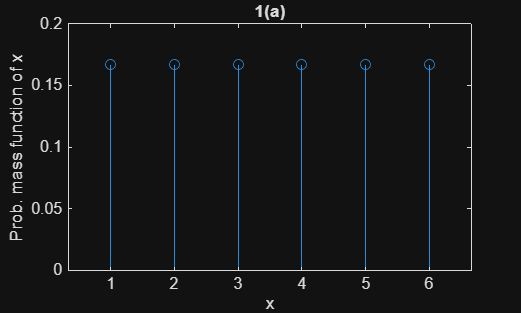

xx = 1:6;
yy = (1/6) * ones(size(xx));
stem(xx,yy)
title("1(a)")
ylabel("Prob. mass function of x")
xlabel("x")

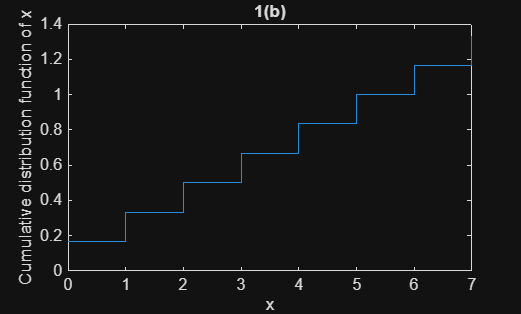


xx = 0:7;
base = (1/6) * ones(size(xx));
yy = cumsum(base);
stairs(xx,yy)
title("1(b)")
ylabel("Cumulative distribution function of x")
xlabel("x")

### Exercicio 2

a)

O espaço de amostragem é o conjunto de todos os resultados possíveis de uma experiência aleatória. Um "evento elementar" é o resultado mais básico e indivisível dessa experiência.

Nº total de notas = 100

A probabilidade de tirar uma nota especifica é 1 em 100

prob = 1/100

b)

X é capaz de ter estes valores {5, 10, 100}, sendo isto o espaço de amostragem.

Se X = 5 a probabilidade de sair uma nota com valor '5' é 9 em 100.

Ou seja, 90/100 = 0.9

Se X = 10 a probabilidade de sair uma nota com valor '10' é 9 em 100.

Ou seja, 9/100 = 0.09

Se X = 100 a probabilidade de sair uma nota com valor '100' é 1 em 100.

Ou seja, 1/100 = 0.01

c)

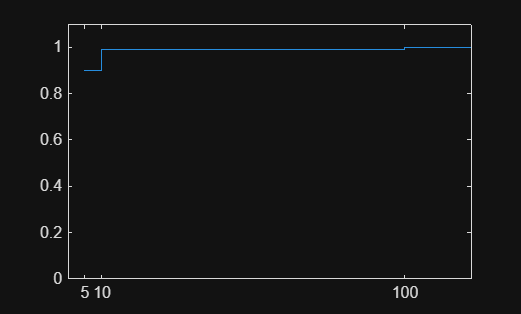

% Adicionamos um valor extra (ex: 120) para a linha do gráfico não acabar no 100
x = [5 10 100 120];

% A probabilidade do valor extra é 0, para não alterar a soma cumulativa!
px = [0.9 0.09 0.01 0]; 

% Cálculo da CDF
Fx = cumsum(px);

% Desenhar o gráfico
stairs(x, Fx)

% Forçar o eixo do x a mostrar apenas os números do teu espaço de amostragem
xticks([5 10 100])

% Limite no eixo dos yy
ylim([0 1.1])

### Exercicio 3

a) Estimar a PMF por simulação

Espaço de amostragem de X (em 4 lançamentos quais as possibilidades de ver cara): {0, 1, 2, 3, 4}

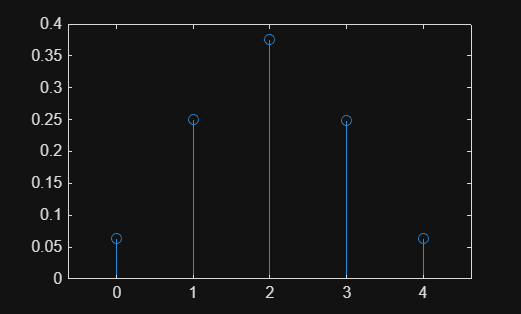

% Num de experiencias
N = 10e5;
X = 0:4;

lancamentos = randi([0 1], N, 4);
soma = sum(lancamentos, 2);
Px = zeros(1, length(X));
for i = 1:length(X)

    casos_fav = sum(soma == X(i));
    Px(i) = casos_fav / N;

end

stem(X, Px)

b)

**Valor esperado / Média**

Calcula-se somando todos os valores possíveis do teu espaço de amostragem (x_i), mas ponderando cada um pela sua probabilidade de ocorrer ( p_X(x_i) ). A fórmula matemática é:

% X e Px foram calculados na alinea a)
media = sum(X .* Px)

media = 1.9986

**Variância**

A variância diz-nos o quão "espalhados" estão os resultados à volta da média. A forma mais eficiente de a calcular usando probabilidades é com a fórmula:

E[X^2] calcula-se exatamente da mesma forma que o Valor Esperado, mas eleva-se todos os valores do espaço de amostragem ao quadrado:

% X e Px foram calculados na alinea a)
x2 = X .^2;
EX2 = sum(x2 .* Px);

varX = EX2 - media^2

varX = 1.0013

**Desvio Padrão**

O **Desvio Padrão** é simplesmente a raiz quadrada da variância.

desvio = sqrt(varX)

desvio = 1.0007

c)

Pequeno resumo antes da resposta:

**Distribuições Discretas **

(Usadas quando o resultado é um número inteiro, ou seja, algo que se pode "contar", como número de tentativas, de sucessos, etc.)

- **Bernoulli:** Modela uma única experiência básica que tem apenas dois resultados possíveis: "sucesso" (assume o valor 1) ou "fracasso" (assume o valor 0).

- *Parâmetro:* p (probabilidade de sucesso).

- **Binomial:** Modela o número total de sucessos que ocorrem ao fim de n experiências de Bernoulli independentes.

- *Parâmetros:* n (número total de experiências) e p (probabilidade de sucesso em cada uma).

- **Geométrica:** Modela o número de vezes que precisas de repetir uma experiência de Bernoulli até conseguires obter o *primeiro* sucesso.

- *Parâmetro:* p (probabilidade de sucesso).

- **Poisson:** Foca-se no número de ocorrências num determinado intervalo de tempo contínuo ou numa região do espaço. **Não tem** um número fixo de experiências (n), sendo muito útil para modelar a chegada de clientes a um banco ou de mensagens numa rede. Pode também ser usada para aproximar a distribuição Binomial quando o n é muito grande e o p é muito pequeno.

- *Parâmetro:* \lambda (taxa ou valor médio de ocorrências).

**Distribuições Contínuas** 

(Usadas quando a variável pode assumir qualquer valor dentro de um intervalo da reta real, ou seja, coisas que se "medem", como tempo, peso, altura, etc.)

- **Uniforme:** Usada quando todos os valores dentro de um intervalo [a, b] têm exatamente a mesma probabilidade de ocorrer (a densidade é constante).

- *Parâmetros:* a (limite inferior) e b (limite superior).

- **Normal (ou Gaussiana):** É a famosa curva em forma de "sino", simétrica em torno da média. Adequa-se a muitas características da natureza e humanas (altura, peso, testes de inteligência) e surge quando vários efeitos independentes se acumulam.

- *Parâmetros:* m ou \mu (média) e \sigma^2 (variância).

- **Exponencial:** Modela frequentemente tempos de espera, como o tempo até um computador avariar ou o tempo entre a chegada de utentes a um hospital. Tem uma propriedade muito particular de "ausência de memória", ou seja, o facto de um sistema já estar a funcionar há 100 horas não altera a probabilidade de ele falhar nas próximas 2 horas.

- *Parâmetro:* \lambda (taxa de ocorrência).

**Outras Distribuições Empíricas**

(Identificadas a partir da observação de dados reais)

- **Lei de Benford:** "Lei dos Primeiros Dígitos", indica que em dados reais (como impostos ou contabilidade), o dígito 1 aparece como primeiro dígito com muito mais frequência (quase 30%) do que os restantes. É muito usada para detetar fraudes.

- **Lei de Zipf:** Relaciona a dimensão ou frequência dos elementos numa lista com a sua ordem de importância. Por exemplo, modela a frequência de palavras num texto (a palavra mais comum aparece o dobro das vezes da 2ª mais comum, etc.).

As características físicas da experiência com as moedas:

- Número fixo de tentativas ou repetições (n = 4 lançamentos).

- Cada tentativa é independente das outras (o resultado de uma moeda não afeta a outra).

- Cada tentativa tem apenas dois resultados possíveis (cara ou coroa).

- A probabilidade de sucesso (p) é constante em todas as tentativas (como a moeda é equilibrada, p = 0.5).

- A nossa variável aleatória X está a contar o **número total de sucessos** nestas n tentativas.

Com base nas distribuições nomeadas acima, para esta experiencia a distribuição correta será a Binomial.

A distribuição Binomial é dada por:

A expressão final fica:

Como 1 - 0.5 = 0.5, pode-se simplificar para:

d)

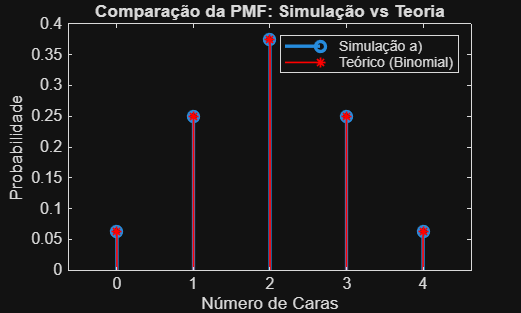

X = 0:4; % Espaço de amostragem
n = 4;   % Número de lançamentos
p = 0.5; % Probabilidade de sucesso

% Calcula a probabilidade teórica exata para o 0, 1, 2, 3 e 4
Px_teorico = binopdf(X, n, p);

% alinea a) (azul)
stem(X, Px, 'LineWidth', 2) 

hold on; 
 
% O 'r*' vermelho (red) e um asterisco
stem(X, Px_teorico, 'r*', 'LineWidth', 1) 


hold off; 

legend('Simulação a)', 'Teórico (Binomial)')
xlabel('Número de Caras')
ylabel('Probabilidade')
title('Comparação da PMF: Simulação vs Teoria')

media_teorica = 2

e)

Com base na TP4

- **Média (Valor Esperado):** E[X] = n * p

- **Variância:** Var(X) = n * p * (1 - p)

% n e p definidos na alinea d)

var_teorica = 1

media_teorica = n * p
var_teorica = n * p * (1 - p)

f)

i)

fi = sum(Px_teorico(3:5))

fi = 0.6875

ii)

fii = sum(Px_teorico(1:2))

iii)

fiii = sum(Px_teorico(2:4))

fii = 0.3125

### Exercicio 4

Número de peças (tentativas): n = 5

Probabilidade de defeito (sucesso da variável): p = 0.30

Espaço de amostragem de X = {0, 1, 2, 3, 4, 5}

a)

N = 10e5;

fiii = 0.8750

n = 5;
p = 0.3;
X = 0:5;

% Matriz N x 5 com 1s (defeito) e 0s (peça boa)
amostras = rand(N, n) < p; 
defeitos_por_amostra = sum(amostras, 2); 

% Função Massa de Probabilidade
Px_sim = zeros(1, length(X));
for i = 1:length(X)
    casos_favoraveis = sum(defeitos_por_amostra == X(i));
    Px_sim(i) = casos_favoraveis / N;
end

% i.
Px_sim

% ii. Gráfico da Função de Distribuição Acumulada
Fx_sim = cumsum(Px_sim);

figure(1);
% Usamos o "ponto fantasma" (ex: o valor 6) para a linha não morrer no 5
stairs([X 6], [Fx_sim Fx_sim(end)], 'LineWidth', 1.5);
title('a) ii. CDF Estimada por Simulação');
xlabel('Número de peças defeituosas (X)');
ylabel('Probabilidade Acumulada F_X(X)');
xticks(0:5);
ylim([0 1.1]);

Px_sim =     0.1679    0.3601    0.3089    0.1322    0.0283    0.0025



% iii. Probabilidade de ter no máximo 2 peças defeituosas ( X <= 2 )
% Corresponde a X = 0, X = 1 ou X = 2 (posições 1, 2 e 3 do vetor)
prob_max_2_sim = sum(Px_sim(1:3));
fprintf('a) iii. Probabilidade simulada (<= 2 defeitos): %.4f\n', prob_max_2_sim);

b)

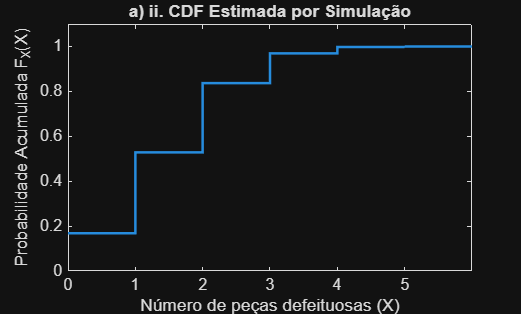

% i. Gráfico da Função de Distribuição Acumulada Teórica
Fx_teorica = binocdf(X, n, p);

figure(2);

stairs([X 6], [Fx_teorica Fx_teorica(end)], 'r', 'LineWidth', 1.5);
title('b) i. CDF Teórica (Distribuição Binomial)');
xlabel('Número de peças defeituosas (X)');
ylabel('Probabilidade Acumulada F_X(X)');
xticks(0:5);

a) iii. Probabilidade simulada (<= 2 defeitos): 0.8370


ylim([0 1.1]);

% ii. Probabilidade de ter no máximo 2 peças defeituosas ( X <= 2 )
% A função binocdf calcula exatamente a definição P(X <= x), logo dá a resposta direta!
prob_max_2_teorica = binocdf(2, n, p);
fprintf('b) ii. Probabilidade teórica (<= 2 defeitos): %.4f\n', prob_max_2_teorica);

**Exercicio 5**

Dado um número fixo de motores por avião (n), sabemos que cada motor pode falhar de forma completamente independente dos outros, e existe uma probabilidade p constante de um motor falhar.

Isto é a definição exata de uma variável com **Distribuição Binomial**.

O enunciado diz que o avião despenha-se se **mais de metade** (> 50%) dos seus motores falharem.

**O Avião de 2 motores (****n=2****):**

- Mais de metade de 2 motores significa que têm de falhar rigorosamente **2 motores** para o avião cair.

- Aplicando a fórmula teórica da Binomial para calcular P(X=2):

**O Avião de 4 motores (****n=4****):**

- Mais de metade de 4 motores significa que o avião só cai se falharem **3 ou 4 motores**.

- Logo, a probabilidade teórica total de queda será a soma dessas duas hipóteses extremas:

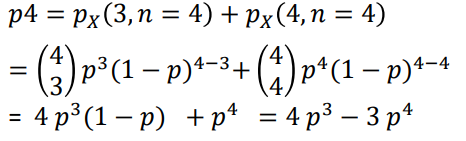

Uma das sugestões no enunciado para resolver o problema é gerar um gráfico para um conjunto de valores concretos de p, permitindo ver visualmente em que situações uma linha ultrapassa a outra.

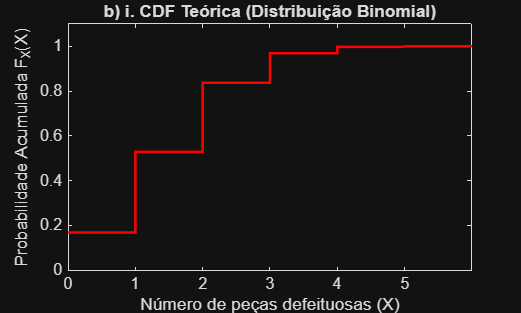

% 1. Criar um vetor com várias probabilidades de falha de um motor (p)
% A sugestão do guião usa logspace para gerar 100 valores desde muito pequenos (10^-3) até 0.5
p = logspace(-3, log10(1/2), 100);

% 2. Calcular a probabilidade de queda para cada avião

P_cair2 = p.^2; 

P_cair4 = 4*p.^3 - 3*p.^4;

% 3. Desenhar o gráfico comparativo

b) ii. Probabilidade teórica (<= 2 defeitos): 0.8369


figure(3);
plot(p, P_cair2, 'b-', 'LineWidth', 1.5)
hold on;
plot(p, P_cair4, 'r--', 'LineWidth', 1.5)
hold off;


legend('2 Motores', '4 Motores', 'Location', 'best')
xlabel('Probabilidade de falha de um único motor (p)')
ylabel('Probabilidade do avião cair')
title('Segurança: Avião de 2 vs 4 Motores')
grid on;

### Exercicio 6

- Número fixo de bits a ser transmitidos (n).

- Cada bit é independente dos outros.

- Cada bit só tem dois resultados possíveis: ou chega bem ("fracasso"), ou chega com erro ("sucesso" da nossa variável).

- A probabilidade de um bit ter erro é constante: p = 10^-5.

a) A alínea pede para calcular a probabilidade de um pacote de **100 Bytes** ser recebido **sem erros** (X = 0).

Como p está em bits, n tambem tem de estar em bits. O número de experiencias será n = 100 * 8 ( 1 byte = 8 bits )

p = 10^-5;

P_cair4 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


n = 100 * 8;
lambda = n * p;

dist_binoA = binopdf(0,n,p)
dist_poissonA = poisspdf(0, lambda)

b)

Agora 1000 Bytes com pelo menos 2 erros.

- Na Binomial, o pacote tem milhares de bits, logo somar as probabilidades de ter 2 erros, 3 erros, 4 erros... até ao limite máximo de bits do pacote.

- Na de Poisson, o espaço de amostragem vai até ao infinito, logo é literalmente impossível somar do 2 até ao infinito.

A melhor solução é calcular através do complemento:

n = 1000 * 8;
lambda = n * p;

dist_binoB = 1 - (binopdf(0,n,p) + binopdf(1,n,p))
dist_poissonB = 1 - (poisspdf(0, lambda) + poisspdf(1, lambda))

### Exercício 7

A distribuição de Poisson é ideal para contar eventos num **intervalo de tempo contínuo** (neste caso, chegadas de e-mails). O único parâmetro que esta distribuição tem é o lambda, que representa o número médio de ocorrências *para o intervalo de tempo*.

**O ****lambda**** é elástico**, ou seja, é necessário ajustar sempre o lambda para o tamanho da "janela de tempo" que a pergunta pede.

a)

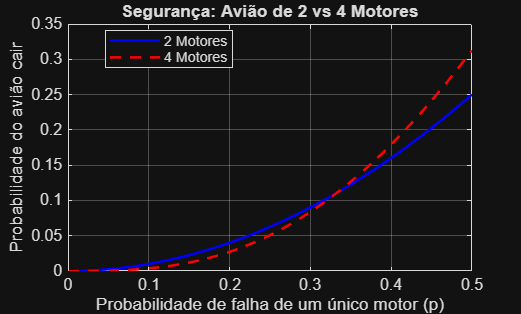

lambda = 5*2;
poisson_teoricoA = sum(poisspdf(0:9, lambda))
% ou poisscdf(9, lambda)


N = 10e5;
sim = poissrnd(lambda,1, N) < 10;
casos_fav = sum(sim);
poisson_simA = casos_fav / N

b)

lambda = 5*5;
poisson_teoricoB = 1 - sum(poisspdf(0:30, lambda))
% ou 1 - poisscdf(30, lambda)

N = 10e5;

dist_binoA = 0.9920

sim = poissrnd(lambda,1, N) > 30;

dist_poissonA = 0.9920

casos_fav = sum(sim);
poisson_simB = casos_fav / N

### Exercício 8

a)

lambda = 1;
mu = 1 / lambda;

x = 0:0.1:10;

dist_binoB = 0.0030

f = exppdf(x,mu);

dist_poissonB = 0.0030

figure(1);

plot(x, f, 'r', 'LineWidth', 2);
title('a) PDF da Distribuição Exponencial (\lambda = 1)');
xlabel('Valores de X');
ylabel('Densidade de Probabilidade f_X(x)');
grid on;

b)

N = 1e5;

poisson_teoricoA = 0.4579

sim = exprnd(mu,1,N);

histogram(sim, 100, 'Normalization', 'pdf', 'EdgeColor', 'none');
hold on;

plot(x, f, 'r', 'LineWidth', 2);

poisson_simA = 0.4584

hold off;

title('b) Simulação vs Teoria (Distribuição Exponencial)');
xlabel('Valores de X');

poisson_teoricoB = 0.1367

ylabel('Densidade de Probabilidade (PDF)');
legend('Histograma (Simulação)', 'Linha Teórica (exppdf)');
grid on; 

### Exercício 9

a)

lambda = 0.2;
mu = 1 / lambda % média teórica
N = 1e5;

poisson_simB = 0.1362


gen = exprnd(mu, 1, N);
mu_sim = mean(gen) % média simulada

b)

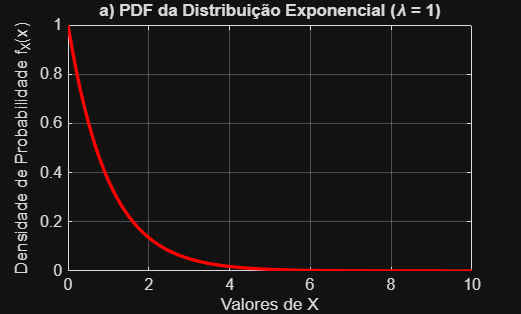

% Provar: P(X > 5 | X > 3) = P(X > 2).
s = 2;
t = 3;

% 1. Calcular P(X > s) de forma direta
% (Quantos casos são > 2, a dividir pelo total de experiências)
prob_s = sum(gen > s) / N;

% 2. Calcular P(X > s+t | X > t) (Probabilidade Condicionada)
% A melhor prática para calcular isto em Matlab:
casos_condicao = sum(gen > t);          % Quantas simulações duraram mais de 3?
casos_favoraveis = sum(gen > (s + t));  % Dentre essas, quantas passaram dos 5?


prob_condicionada = casos_favoraveis / casos_condicao;

fprintf('P(X > %d) = %.4f\n', s, prob_s);
fprintf('P(X > %d | X > %d) = %.4f\n', s+t, t, prob_condicionada);

### Exercicio 10

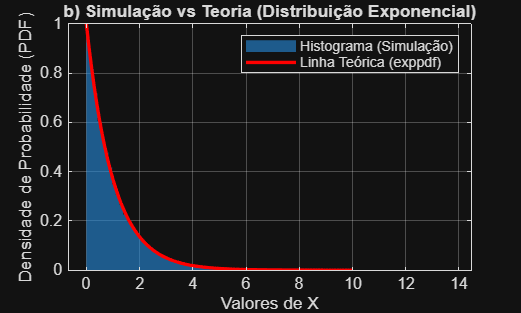

lambdaX = 0.4;
lambdaY = 0.1;
muX = 1 / lambdaX;
muY = 1 / lambdaY;
N = 1e5;

X = exprnd(muX, 1, N);
Y = exprnd(muY, 1, N);

casos_fav = sum(X < Y);
sim = casos_fav / N;


teorica = lambdaX / (lambdaX + lambdaY);

fprintf('Probabilidade Teórica:  %.4f\n', teorica);
fprintf('Probabilidade Simulada: %.4f\n', sim);

### Exercicio 11

O enunciado diz explicitamente que a taxa lambda = 0.02 representa erros **por página**. No entanto, a pergunta quer saber a probabilidade para um livro inteiro de **100 páginas**.

lambda = 0.02 * 100;


mu = 5

probEx11 = sum(poisspdf(0:1, lambda))
% ou poisscdf(1, lambda)

### Exercicio 12

"Qual é a probabilidade do número aleatório de alunos (X) ser menor ou igual à capacidade total das turmas?"

A capacidade total para n turmas é simplesmente C = n * 20. Logo, queremos calcular P(X <= C).

N = 1e5;


mu_sim = 5.0175

media = 100;
desvio = 10;

% Gerar os valores usando o randn (ajustado à média e desvio pretendido)
X = media + desvio * randn(1, N);

turmas = [5, 6, 7];

for n = turmas
    capacidade = n * 20;
    
    % a) Probabilidade Simulada: Fração de vezes que X <= capacidade
    casos_fav = sum(X <= capacidade);
    prob_simulada = casos_fav / N;
    
    % b) Probabilidade Teórica: Usando a CDF da Normal
    prob_teorica = normcdf(capacidade, media, desvio);
    

P(X > 2) = 0.6724


    % Imprimir a comparação

P(X > 5 | X > 3) = 0.6714


    fprintf('Turmas: %d (Capacidade: %d alunos)\n', n, capacidade);
    fprintf('  Simulada: %.4f\n', prob_simulada);
    fprintf('  Teórica:  %.4f\n\n', prob_teorica);
end

- Para **n = 5** (capacidade 100): Como a capacidade é exatamente igual à média (100), a probabilidade de haver 100 alunos ou menos será exatamente metade da curva, ou seja, **50% (0.5000)**.

- Para **n = 6** (capacidade 120): Estás a abranger quase a curva toda (2 desvios padrão acima da média), pelo que a probabilidade salta para perto de **97.7%**.

- Para **n = 7** (capacidade 140): Já estás 4 desvios padrão acima da média. A probabilidade de o número de alunos ficar abaixo de 140 é **100% (1.0000)**.

### Exercício 13

Média de uma bolacha: mu = 20 g

Variância de uma bolacha: sigma^2 = 9 g^2

O peso de um pacote inteiro com n bolachas é a soma de todas elas.

mu = 20;
sigma = 9;

n = randi(100,1);

a)

- O Valor Esperado de uma soma é sempre a soma dos Valores Esperados.

- A Variância de uma soma só é igual à soma das Variâncias se as variáveis forem independentes (o enunciado diz que são "i.i.d.")

ESn = n*20;
var = n*9;

b)

A alínea pede para descobrir um limite superior para a probabilidade de uma única bolacha pesar 30 gramas ou mais (P(X >= 30)), **usando apenas a média** (ignorando a variância).

Sempre que pedem um "majorante" ou "upper bound" usando *apenas* médias, a ferramenta universal é a **Desigualdade de Markov**. 

A fórmula teórica:

(Desde que a variável só assuma valores positivos, o que é o caso do peso de uma bolacha)

probB = 20 / 30

c)

A alinea pede para limitar a probabilidade de uma única bolacha desviar-se da sua média em mais de 10 gramas, **usando a média e a variância**.

Sempre que o enunciado dá a variância (sigma^2) e pede para limitar a probabilidade de um valor se desviar, a ferramenta matemática universal é a **Desigualdade de Chebyshev** .

A fórmula teórica:

(A probabilidade de a distância entre o valor e a média ser maior ou igual a a, é menor ou igual à variância a dividir por a^2)

a = 10;
probC = 9/10^2

d)

O TLC (Teorema do Limite Central) diz que, independentemente da forma que a distribuição original tenha (neste caso, o peso de uma bolacha individual), se **somar-mos muitas variáveis independentes** (n grande, geralmente > 30), essa **soma vai ter sempre uma Distribuição Normal (Gaussiana).**

Como n = 100 bolachas, o peso total S_{100} segue uma distribuição Normal. E para usar o normcdf do Matlab, só é necessário de duas informações:

- A Média

- O Desvio Padrão ( raiz quadrada da Variância)

n = 100;

% pacote inteiro (S_100)
mu_pacote = n * 20;
var_pacote = n * 9;
desvio_pacote = sqrt(var_pacote);

Probabilidade Teórica:  0.8000


Probabilidade Simulada: 0.7990


% Calcular a probabilidade do intervalo [1970, 2030]
% P(1970 <= S100 <= 2030) = CDF(2030) - CDF(1970)
prob_max = normcdf(2030, mu_pacote, desvio_pacote);
prob_min = normcdf(1970, mu_pacote, desvio_pacote);

probD = prob_max - prob_min;

fprintf('d) Probabilidade do pacote pesar entre 1970g e 2030g (TLC): %.4f\n', probD);

probEx11 = 0.4060

Turmas: 5 (Capacidade: 100 alunos)


  Simulada: 0.4998


  Teórica:  0.5000



Turmas: 6 (Capacidade: 120 alunos)


  Simulada: 0.9768


  Teórica:  0.9772



Turmas: 7 (Capacidade: 140 alunos)


  Simulada: 1.0000


  Teórica:  1.0000



probB = 0.6667

probC = 0.0900

d) Probabilidade do pacote pesar entre 1970g e 2030g (TLC): 0.6827
